alpha = 1+ mod(273,3)

alpha = 1

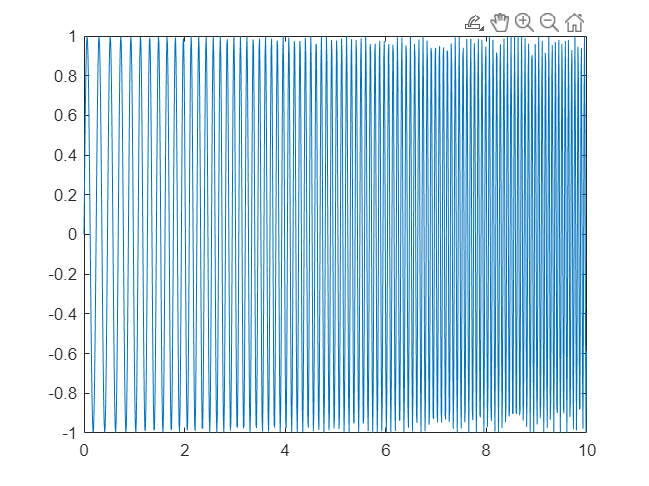

Fs = 100; 
T = 10; 
t = 0:1/Fs:T-1/Fs;  
F_start = 2 + 2*alpha;
F_end = 5 + 5*alpha;
chirp_signal = sin(2*pi.*(linspace(F_start, F_end, length(t))).*t);


plot(t, chirp_signal);

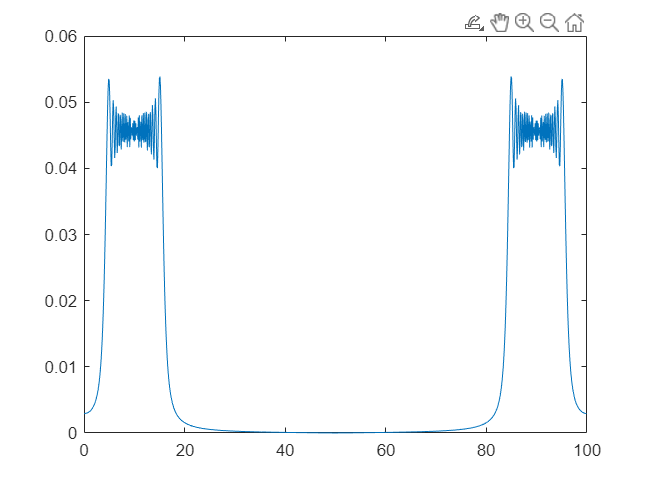


N = length(chirp_signal);
frequencies = (Fs/N)*(0:N-1);
spectrum = fft(chirp_signal);
plot(frequencies, abs(spectrum)/N);

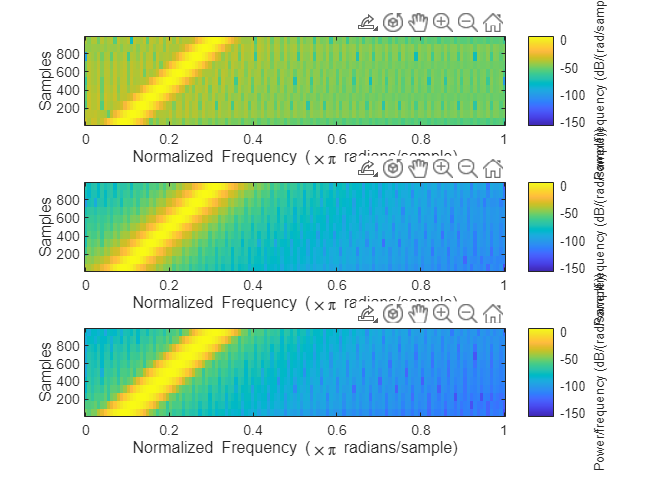

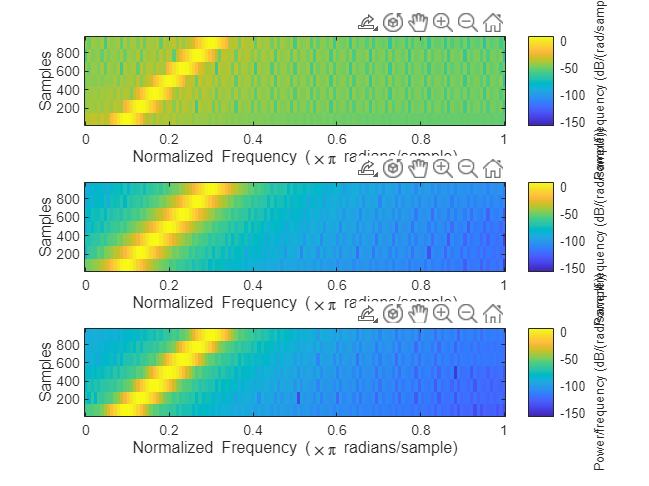

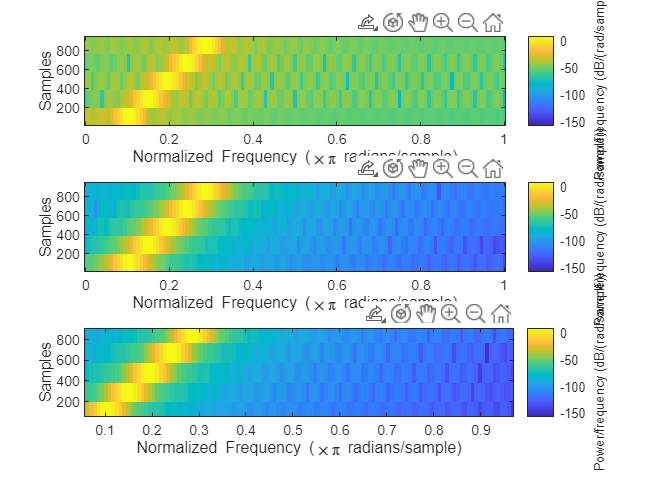


window_lengths = [100, 150, 200];
windowing_techniques = {'hamming', 'hanning', 'blackman'};

overlap = 10;

for i = 1:length(window_lengths)
    for j = 1:length(windowing_techniques)
        window_length = window_lengths(i);
        window_type = windowing_techniques{j};
        subplot(length(window_lengths),1,j);
        window = eval([window_type, '(', num2str(window_length), ')']);
        spectrogram(chirp_signal, window, overlap);
    end
    figure;
end

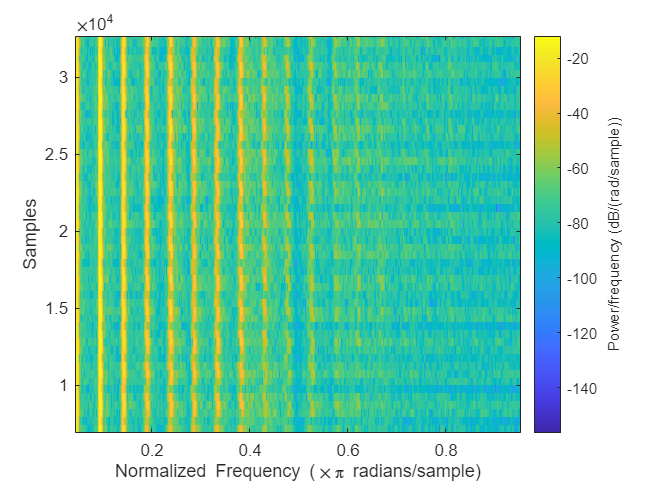


audio_file_instru = 'instru1.wav';
audio_file_opera = 'opera.wav';

instru_audio = audioread(audio_file_instru);
opera_audio = audioread(audio_file_opera);

Fs = 44100; 
window_length = 1024; 
overlap = window_length/2;
spectrogram(instru_audio,blackman(window_length), overlap);

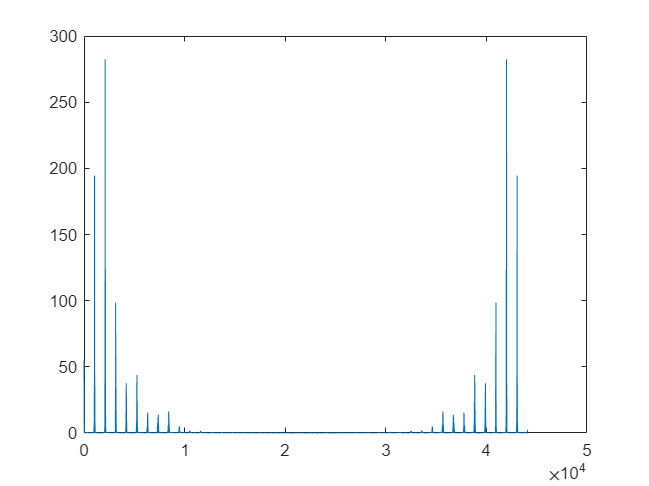


N = length(instru_audio);
frequencies = (Fs/N)*(0:N-1);
spectrum = fft(instru_audio);
plot(frequencies, abs(spectrum));

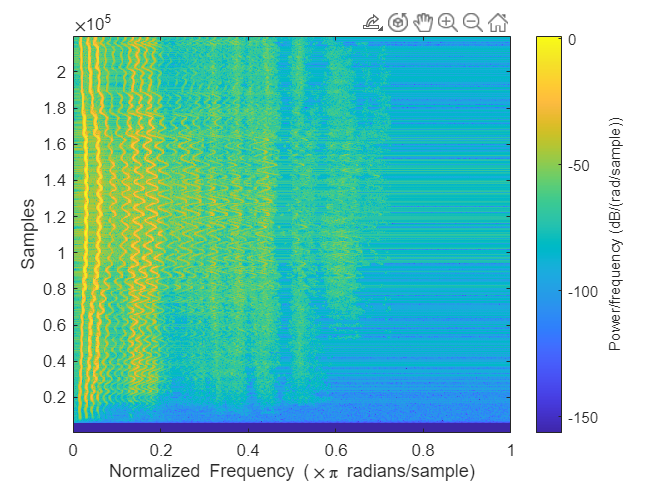


spectrogram(opera_audio, window_length, overlap);

fs = 4000; % Sampling rate (in Hz)
duration = 3; % Duration of the recording (in seconds)

% Create an audio recorder object
recObj = audiorecorder(fs, 16, 1); % 16-bit, mono

% Start recording
disp('Start speaking...');

Start speaking...


recordblocking(recObj, duration);
disp('End of recording.');

End of recording.



% Store the recorded audio data
audioData = getaudiodata(recObj);

% Save the recorded audio as a .wav file
filename = 'name.wav';
audiowrite(filename, audioData, fs);

% Display a message indicating the file has been saved
disp(['Audio saved as ' filename]);

Audio saved as name.wav


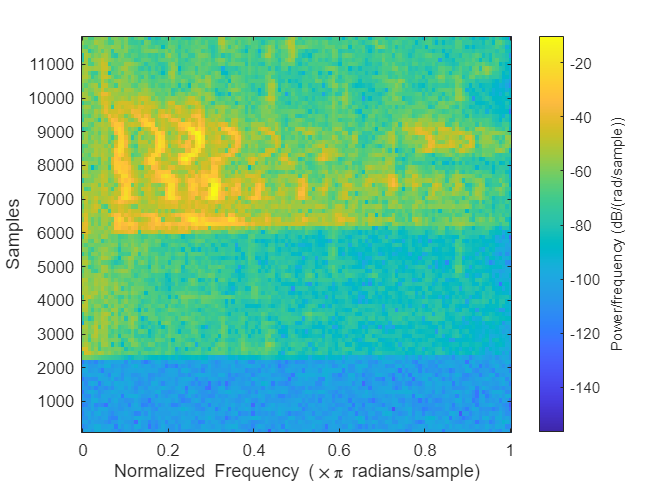


[y,Fs] = audioread("name.wav");
window_length = 256; 
overlap = window_length / 2; 

spectrogram(y, window_length, overlap);